## **Feature Manipulation Experiment 5**

**In this notebook we will crate a SHH (SHH 5) containing three solvers: **

**1) HH1: a hyper-heuristic with LPT and SPT as solvers**

**2) HH2: a hyper-heuristic with MPA and SPT as solvers**

**3) HH3: a hyper-heuristic with MPA and LPA as solvers**

**The instances to solve are I1 to I5 from previous experiments. **

**We just need to find the right model able to choose between the three solvers to successfully solve all instances. **

**The files needed for this notebook to run are: **

**FM_I1.mat, FM_I2.mat, FM_I3.mat, FM_I4.mat, FM_I5.mat, LPT.mat, SPT.mat, MPA.mat, FM_HH1.mat, FM_HH1_multi.mat, FM_HH2.mat, FM_HH2_multi.mat, FM_HH3.mat, FM_HH3_multi.mat, FM_Exp5_Results.mat**

**CLEANING AND FOLDERS**

%First let's clean everything and add needed folders
clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities

**LOADING FILES**

%Loading instance I1, I2, I3, I4 and I5
load("FM_I1.mat")
load("FM_I2.mat")
load("FM_I3.mat")
load("FM_I4.mat")
load("FM_I5.mat")

%For precaution let's reset the instances 
I1.reset
I2.reset
I3.reset
I4.reset
I5.reset
InstanceSet={I1 I2 I3 I4 I5};

%Loading heuristics
load('LPT.mat')
load('SPT.mat')
load('MPA.mat')
load('MPA_multi.mat')
load('LPA.mat')

%Loading HH1
load('FM_HH1.mat')
load('FM_HH1_multi.mat')

%Loading HH2
load('FM_HH2.mat')
load('FM_HH2_multi.mat')

%Loading HH3
load('FM_HH3.mat')
load('FM_HH3_multi.mat')

%Loading results from Exp4
load("FM_Exp4_Results.mat")

**INITIAL VISUALIZATION**

%Let's see how our solvers perform in our instance set
Results{1,5}='Instance 4';
Results{1,6}='Instance 5';
Results{7,1}='HH2';
Results{8,1}='HH3';
Results{9,1}='SHH5';


%solving set with all solvers and updating Results 
solvedInstances_LPT=LPT.solveInstanceSet(InstanceSet);
solvedInstances_SPT=SPT.solveInstanceSet(InstanceSet);
solvedInstances_MPA=MPA.solveInstanceSet(InstanceSet);
solvedInstances_LPA=LPA.solveInstanceSet(InstanceSet);
solvedInstances_HH1=FM_HH1.solveInstanceSet(InstanceSet);
solvedInstances_HH3=FM_HH3.solveInstanceSet(InstanceSet);
solvedInstances_HH2=FM_HH2.solveInstanceSet(InstanceSet);

Results{2,2}=solvedInstances_LPT{1}.solution.makespan;
Results{3,2}=solvedInstances_SPT{1}.solution.makespan;
Results{4,2}=solvedInstances_MPA{1}.solution.makespan;
Results{5,2}=solvedInstances_LPA{1}.solution.makespan;
Results{6,2}=solvedInstances_HH1{1}.solution.makespan;
Results{7,2}=solvedInstances_HH2{1}.solution.makespan;
Results{8,2}=solvedInstances_HH3{1}.solution.makespan;

Results{2,3}=solvedInstances_LPT{2}.solution.makespan;
Results{3,3}=solvedInstances_SPT{2}.solution.makespan;
Results{4,3}=solvedInstances_MPA{2}.solution.makespan;
Results{5,3}=solvedInstances_LPA{2}.solution.makespan;
Results{6,3}=solvedInstances_HH1{2}.solution.makespan;
Results{7,3}=solvedInstances_HH2{2}.solution.makespan;
Results{8,3}=solvedInstances_HH3{2}.solution.makespan;

Results{2,4}=solvedInstances_LPT{3}.solution.makespan;
Results{3,4}=solvedInstances_SPT{3}.solution.makespan;
Results{4,4}=solvedInstances_MPA{3}.solution.makespan;
Results{5,4}=solvedInstances_LPA{3}.solution.makespan;
Results{6,4}=solvedInstances_HH1{3}.solution.makespan;
Results{7,4}=solvedInstances_HH2{3}.solution.makespan;
Results{8,4}=solvedInstances_HH3{3}.solution.makespan;


Results{2,5}=solvedInstances_LPT{4}.solution.makespan;
Results{3,5}=solvedInstances_SPT{4}.solution.makespan;
Results{4,5}=solvedInstances_MPA{4}.solution.makespan;
Results{5,5}=solvedInstances_LPA{4}.solution.makespan;
Results{6,5}=solvedInstances_HH1{4}.solution.makespan;
Results{7,5}=solvedInstances_HH2{4}.solution.makespan;
Results{8,5}=solvedInstances_HH3{4}.solution.makespan;

Results{2,6}=solvedInstances_LPT{5}.solution.makespan;
Results{3,6}=solvedInstances_SPT{5}.solution.makespan;
Results{4,6}=solvedInstances_MPA{5}.solution.makespan;
Results{5,6}=solvedInstances_LPA{5}.solution.makespan;
Results{6,6}=solvedInstances_HH1{5}.solution.makespan;
Results{7,6}=solvedInstances_HH2{5}.solution.makespan;
Results{8,6}=solvedInstances_HH3{5}.solution.makespan;

Results

Results = 9×6 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 4'}    {'Instance 5'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   48.1692]}    {[   40.0000]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   28.1692]}    {[   40.0000]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   48.1692]}    {[   40.0000]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   50.8974]}    {[   20.0000]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   50.8885]}    {[   40.0000]}
    {'HH2'     }    {[          61]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}    {[   40.0000]}
    {'HH3'     }    {[          49]}    {[     41.0665]}    {[     33.0303]}    {[   50.8974]}    {[   20.0000]}
    {'SHH5'    }    {0×0 double    }    {0×0 double    }    {0×0 double

**Our goal is to create a SHH that chooses among HH1, HH2 and HH3 to properly solve the 5 instances.**

**Let's create SHH5:**

%Creating SHH5
props = struct('nbLayers',2,'selectedSolvers',1:3,...
                 'nbRules',3,'innerHHs',[FM_HH1_multi FM_HH2_multi FM_HH3_multi],'selectedFeatures', [1]);
FM_SHH5=ruleBasedSelectionHHMulti(props)

FM_SHH5 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
In matlab.internal.editor/VariableOutputPackager/isolatedDisplaying
In matlab.internal.editor/VariableOutputPackager/getStringFromVar
In matlab.internal.editor/VariableOutputPackager/getTruncatedStringFromVar
In matlab.internal.editor/VariableOutputPackager/packageVarOther
In matlab.internal.editor/VariableOutputPackager/packageOutput
In LiveEditorEvalua

**Solving with SHH5 **

solvedInstances_SHH5=FM_SHH5.solveInstanceSet(InstanceSet);

Results{9,2}=solvedInstances_SHH5{1}.solution.makespan;
Results{9,3}=solvedInstances_SHH5{2}.solution.makespan;
Results{9,4}=solvedInstances_SHH5{3}.solution.makespan;
Results{9,5}=solvedInstances_SHH5{4}.solution.makespan;
Results{9,6}=solvedInstances_SHH5{5}.solution.makespan;
Results

Results = 9×6 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 4'}    {'Instance 5'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   48.1692]}    {[   40.0000]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   28.1692]}    {[   40.0000]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   48.1692]}    {[   40.0000]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   50.8974]}    {[   20.0000]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   50.8885]}    {[   40.0000]}
    {'HH2'     }    {[          61]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}    {[   40.0000]}
    {'HH3'     }    {[          49]}    {[     41.0665]}    {[     33.0303]}    {[   50.8974]}    {[   20.0000]}
    {'SHH5'    }    {[          49]}    {[     41.0665]}    {[     33.0

**The SHH5 is very unlikely to perform well as the initial model is random. Let's now try to find a model that is able to appropiately choose among the three HHs. We want the model to solve I1 with HH1, I2 with either HH1 or HH2, I3 with either HH2 or HH3, I4 with HH2, and I5 with HH3.**

**Let's look at the features of all instances for any insights: **

I1.getFeatureVector([1 2 3 4 5])

ans =     0.2812    0.4380    0.5413    0.6667    0.2500


I2.getFeatureVector([1 2 3 4 5])

ans =     0.0749    0.1805    0.1765    0.4074    0.1250


I3.getFeatureVector([1 2 3 4 5])

ans =     0.0751    0.0615    0.3064    0.4074    0.1250


I4.getFeatureVector([1 2 3 4 5])

ans =     0.2544    0.3334    0.3767    0.6667    0.3333


I5.getFeatureVector([1 2 3 4 5])

ans =          0    0.4923    0.4015    0.2963    0.0417


**Creating a model**

%Creating the SHH5 model
SHH5_model=[0.2 1; 0.1 2; 0 3];
FM_SHH5.value=SHH5_model;


%Solving the instance set and updating the values 
solvedInstances_SHH5=FM_SHH5.solveInstanceSet(InstanceSet);

Results{9,2}=solvedInstances_SHH5{1}.solution.makespan;
Results{9,3}=solvedInstances_SHH5{2}.solution.makespan;
Results{9,4}=solvedInstances_SHH5{3}.solution.makespan;
Results{9,5}=solvedInstances_SHH5{4}.solution.makespan;
Results{9,6}=solvedInstances_SHH5{5}.solution.makespan;
Results

Results = 9×6 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 4'}    {'Instance 5'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   48.1692]}    {[   40.0000]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   28.1692]}    {[   40.0000]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   48.1692]}    {[   40.0000]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   50.8974]}    {[   20.0000]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   50.8885]}    {[   40.0000]}
    {'HH2'     }    {[          61]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}    {[   40.0000]}
    {'HH3'     }    {[          49]}    {[     41.0665]}    {[     33.0303]}    {[   50.8974]}    {[   20.0000]}
    {'SHH5'    }    {[          42]}    {[     21.0665]}    {[     33.0

**So far the only problem is the instance 4, for it let's add another feature. **

%Adding an extra feature to the model 
props = struct('nbLayers',2,'selectedSolvers',1:3,...
                 'nbRules',3,'innerHHs',[FM_HH1_multi FM_HH2_multi FM_HH3_multi],'selectedFeatures', [1 4]);
FM_SHH5=ruleBasedSelectionHHMulti(props);


%Creating the SHH5 model
SHH5_model=[0.2 0.7 1; 0.1 0.66 2; 0 0.3 3];
FM_SHH5.value=SHH5_model;


%Solving the instance set and updating the values 
solvedInstances_SHH5=FM_SHH5.solveInstanceSet(InstanceSet);

Results{9,2}=solvedInstances_SHH5{1}.solution.makespan;
Results{9,3}=solvedInstances_SHH5{2}.solution.makespan;
Results{9,4}=solvedInstances_SHH5{3}.solution.makespan;
Results{9,5}=solvedInstances_SHH5{4}.solution.makespan;
Results{9,6}=solvedInstances_SHH5{5}.solution.makespan;
Results

Results = 9×6 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 4'}    {'Instance 5'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   48.1692]}    {[   40.0000]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   28.1692]}    {[   40.0000]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   48.1692]}    {[   40.0000]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   50.8974]}    {[   20.0000]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   50.8885]}    {[   40.0000]}
    {'HH2'     }    {[          61]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}    {[   40.0000]}
    {'HH3'     }    {[          49]}    {[     41.0665]}    {[     33.0303]}    {[   50.8974]}    {[   20.0000]}
    {'SHH5'    }    {[          42]}    {[     21.0665]}    {[     33.0

**With a second feature we could improve a bit, but it was not enough, let's try a third one.**

%Adding an extra feature to the model 
props = struct('nbLayers',2,'selectedSolvers',1:3,...
                 'nbRules',3,'innerHHs',[FM_HH1_multi FM_HH2_multi FM_HH3_multi],'selectedFeatures', [1 3 4]);
FM_SHH5=ruleBasedSelectionHHMulti(props);


%Creating the SHH5 model
SHH5_model=[0.2 0.55 0.7 1; 0.1 0.37 0.66 2; 0 0.4 0.3 3];
FM_SHH5.value=SHH5_model;


%Solving the instance set and updating the values 
solvedInstances_SHH5=FM_SHH5.solveInstanceSet(InstanceSet);

Results{9,2}=solvedInstances_SHH5{1}.solution.makespan;
Results{9,3}=solvedInstances_SHH5{2}.solution.makespan;
Results{9,4}=solvedInstances_SHH5{3}.solution.makespan;
Results{9,5}=solvedInstances_SHH5{4}.solution.makespan;
Results{9,6}=solvedInstances_SHH5{5}.solution.makespan;
Results

Results = 9×6 cell array
    {0×0 double}    {["Instance 1"]}    {["Instance 2"]}    {["Instance 3"]}    {'Instance 4'}    {'Instance 5'}
    {["LPT"   ]}    {[          41]}    {[     41.0665]}    {[     72.4897]}    {[   48.1692]}    {[   40.0000]}
    {["SPT"   ]}    {[          61]}    {[     21.0665]}    {[     73.0239]}    {[   28.1692]}    {[   40.0000]}
    {["MPA"   ]}    {[          58]}    {[     41.0665]}    {[     33.0303]}    {[   48.1692]}    {[   40.0000]}
    {'LPA'     }    {[          41]}    {[     41.0665]}    {[     72.4882]}    {[   50.8974]}    {[   20.0000]}
    {'HH1'     }    {[          42]}    {[     21.0665]}    {[     73.0239]}    {[   50.8885]}    {[   40.0000]}
    {'HH2'     }    {[          61]}    {[     21.0665]}    {[     33.0303]}    {[   28.1692]}    {[   40.0000]}
    {'HH3'     }    {[          49]}    {[     41.0665]}    {[     33.0303]}    {[   50.8974]}    {[   20.0000]}
    {'SHH5'    }    {[          42]}    {[     21.0665]}    {[     33.0

**Finally, the third feature helped to make the right decisions.**

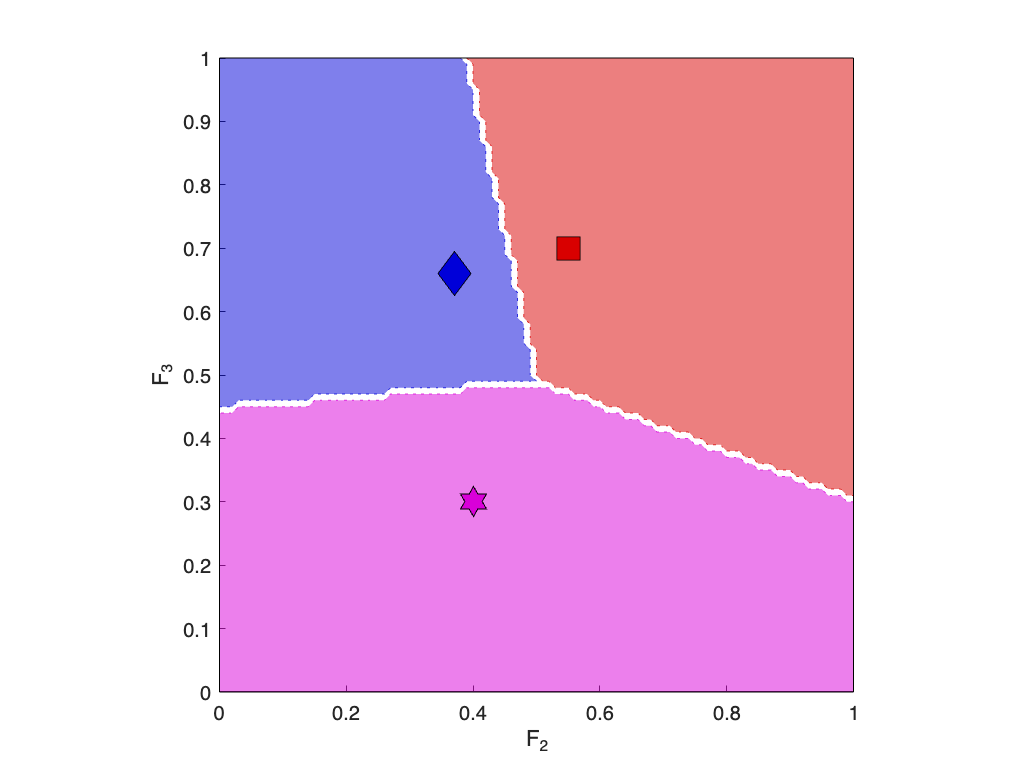

ans =     0.3242    0.2330    0.4277


FM_SHH5.plotZones(0:0.01:1,1,[2 3],1)

%FM_SHH5.plotFeatureMap(InstanceSet,"full",struct('features',[1 2]),true,1)

**Saving variables **

save('FM_SHH5','FM_SHH5')
save('FM_Exp5_Results','Results')